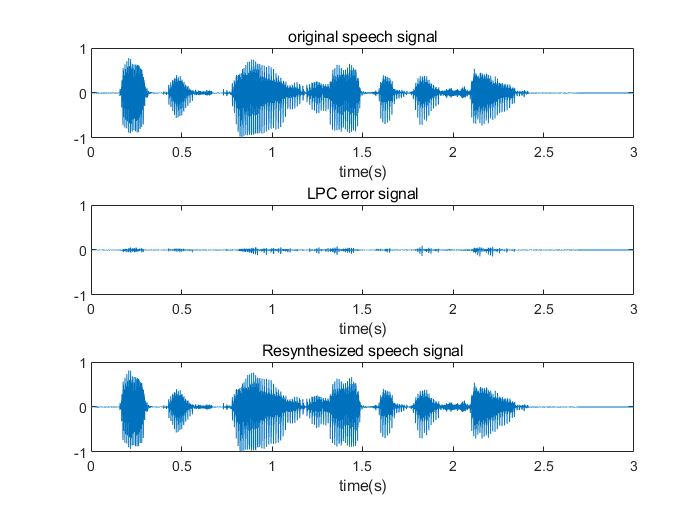

[s,fs]=audioread('s5.wav');
framesize=320;
frameshift=80;
order=12;
sig_hat=zeros(1,length(s));
window=hamming(framesize);

[a0,error0]=LPC(s(1:framesize)'.*window',order);
sig_hat(1:framesize)=s(1:framesize)'-error0;



for n=2:(length(s)-framesize)/frameshift

    frame=s((n-1)*frameshift+1:(n-1)*frameshift+framesize)'.*window';

    [a,error]=LPC(frame,order);

    sig_hat((n-1)*frameshift+1:(n-1)*frameshift+framesize)=s((n-1)*frameshift+1:(n-1)*frameshift+framesize)'-error;
    
end
error_whole=s'-sig_hat;
 
figure;
subplot(3,1,1);
t=1/fs:1/fs:length(s)/fs;
plot(t,s');
title('original speech signal');
xlabel('time(s)');

subplot(3,1,2);
plot(t,error_whole);
title('LPC error signal');
xlabel('time(s)');
axis([0,length(s)/fs,-1,1]);

subplot(3,1,3)
plot(t,sig_hat);
title('Resynthesized speech signal');
xlabel('time(s)');
axis([0,length(s)/fs,-1,1]);